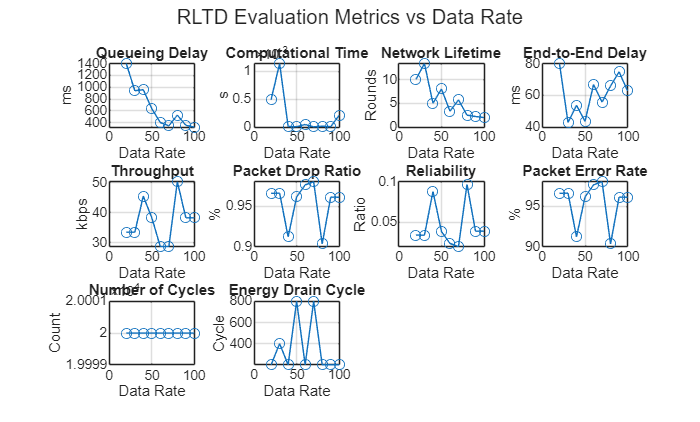

% RLTD Routing Protocol for WBAN - Updated with PER, Cycles, Energy Drain Cycle
% Packet Error Rate, Number of Cycles, and Energy Drain Cycle
clc; clear;

%% Parameters
areaSize = 200; % cm
numRelays = 12;
numSources = 8;
numSink = 1;
numNodes = numRelays + numSources + numSink; % 21 nodes
range = 50; % cm
initialEnergy = 50;
energyThreshold = 0.2 * initialEnergy;
tempThreshold = 42; % °C
tempBase = 36 + rand(numNodes,1)*7;
reliabilityThreshold = 0.6;
packetSize = 1500; % bytes
dataRates = 20:10:100; % kbps
simTime = 1000; % seconds
queueDelayBase = 5; queueVar = 10;

%% Initialize Network
roles = [repmat("Relay", 1, numRelays), repmat("Source", 1, numSources), "Sink"];
positions = rand(numNodes, 2) * areaSize;
energyOriginal = initialEnergy * ones(numNodes, 1);
sinkID = numNodes;

%% Load Sensor Data
sensorData = readmatrix('DATA.csv');
if size(sensorData,2) ~= numSources
    error('Expected 8 columns of sensor data for 8 source nodes.');
end

numCycles = size(sensorData,1); % New metric

%% Metric Initialization
metrics = zeros(length(dataRates), 10); % 7 original + PER, Cycles, EnergyDrainCycle
energyPerSource = zeros(length(dataRates), numSources);
transmissionLog = strings(numCycles, numSources);

%% Start Simulation
for drIdx = 1:length(dataRates)
    dataRate = dataRates(drIdx);
    energy = energyOriginal;
    nodeDead = false(numNodes, 1);
    RLTD_Cost = inf(numNodes, 1);
    tStart = tic;
    energyDrainCycle = 0;

    % RLTD Cost Metrics
    SNR = 10 + rand(numNodes, 1) * 20;
    SINR = SNR - (1 + rand(numNodes, 1) * 5);
    interferenceRatio = SINR ./ SNR;
    Delay = rand(numNodes,1) * 100;
    LQI = interferenceRatio + Delay;
    reliability = rand(numNodes, 1);
    HopCount = randi([1, 4], numNodes, 1);
    numMalicious = randi([1, 3]);
    maliciousNodes = randperm(numRelays, numMalicious);

    % RLTD Cost Computation
    for i = 1:numNodes-1
        if energy(i) >= energyThreshold && tempBase(i) <= tempThreshold && ...
           reliability(i) >= reliabilityThreshold && ~ismember(i, maliciousNodes)
            RLTD_Cost(i) = 0.4 * LQI(i) + 0.2 * tempBase(i) + 0.2 * Delay(i) + 0.2 * HopCount(i);
        end
    end
    tComp = toc(tStart) / dataRate;

    % Metric Counters
    totalQueueDelay = 0;
    totalE2EDelay = zeros(numCycles, 1);
    networkLifetime = 0;
    totalPacketsSent = 0;
    totalPacketsReceived = 0;
    totalPacketsDropped = 0;
    queueFluctuation = 1 + 0.3 * sin(1:numCycles);

    for t = 1:numCycles
        roundE2EDelay = 0; validCount = 0;

        for s = 1:numSources
            srcID = numRelays + s;
            if nodeDead(srcID), continue; end

            totalPacketsSent = totalPacketsSent + 1;
            transmissionLog(t, s) = "00";

            dists = vecnorm(positions - positions(srcID,:), 2, 2);
            eligible = find(dists <= range & RLTD_Cost < inf & roles == "Relay" & ...
                            ~nodeDead & tempBase <= tempThreshold);

            eligible = eligible(eligible <= numNodes);
            if isempty(eligible)
                totalPacketsDropped = totalPacketsDropped + 1;
                continue;
            end

            eligibleCosts = RLTD_Cost(eligible);
            [~, bestIdx] = min(eligibleCosts);
            nextHop = eligible(bestIdx);

            % Queue Delay
            qDelay = (queueDelayBase + rand() * queueVar) * queueFluctuation(t);
            totalQueueDelay = totalQueueDelay + qDelay;
            roundE2EDelay = roundE2EDelay + qDelay + Delay(nextHop);

            % Energy Drain
            energy([srcID, nextHop]) = energy([srcID, nextHop]) - 0.05;

            for n = [srcID, nextHop]
                if energy(n) < energyThreshold && ~nodeDead(n)
                    nodeDead(n) = true;
                    if networkLifetime == 0
                        networkLifetime = t;
                    end
                end
            end

            % Energy Drain Cycle Tracking
            if energyDrainCycle == 0 && any(energy(numRelays+1:numRelays+numSources) < energyThreshold)
                energyDrainCycle = t;
            end

            if nodeDead(srcID) || nodeDead(nextHop)
                totalPacketsDropped = totalPacketsDropped + 1;
            else
                totalPacketsReceived = totalPacketsReceived + 1;
                transmissionLog(t, s) = "01";
            end

            validCount = validCount + 1;
        end

        if validCount > 0
            totalE2EDelay(t) = roundE2EDelay / validCount;
        else
            totalE2EDelay(t) = NaN;
        end
    end

    % Final metric computation
    throughput = (totalPacketsReceived * packetSize * 8) / (simTime * 1000); % kbps
    dropRatio = totalPacketsDropped / totalPacketsSent;
    reliabilityRatio = totalPacketsReceived / totalPacketsSent;
    PER = dropRatio * 100;

    metrics(drIdx, :) = [
        totalQueueDelay / dataRate, ...
        tComp, ...
        networkLifetime / dataRate, ...
        mean(totalE2EDelay(~isnan(totalE2EDelay))), ...
        throughput, ...
        dropRatio, ...
        reliabilityRatio, ...
        PER, ...
        numCycles, ...
        energyDrainCycle
    ];

    for s = 1:numSources
        srcID = numRelays + s;
        energyPerSource(drIdx, s) = initialEnergy - energy(srcID);
    end
end

%% Save Results
writematrix([dataRates(:), metrics(:,1)], 'Queueing_Delay_RLTD.csv');
writematrix([dataRates(:), metrics(:,2)], 'Computational_Time_RLTD.csv');
writematrix([dataRates(:), metrics(:,3)], 'Network_Lifetime_RLTD.csv');
writematrix([dataRates(:), metrics(:,4)], 'End_to_End_Delay_RLTD.csv');
writematrix([dataRates(:), metrics(:,5)], 'Throughput_RLTD.csv');
writematrix([dataRates(:), metrics(:,6)], 'Packet_Drop_Ratio_RLTD.csv');
writematrix([dataRates(:), metrics(:,7)], 'Reliability_RLTD.csv');
writematrix([dataRates(:), metrics(:,8)], 'Packet_Error_Rate_RLTD.csv');
writematrix([dataRates(:), metrics(:,9)], 'Number_of_Cycles_RLTD.csv');
writematrix([dataRates(:), metrics(:,10)], 'Energy_Drain_Cycle_RLTD.csv');
writematrix(energyPerSource, 'Energy_Source_Node_RLTD.csv');
writetable(cell2table(cellstr(transmissionLog)), 'Transmission_Log_RLTD.csv');

%% Plotting
figure;
subplot(3,4,1); plot(dataRates, metrics(:,1), '-o'); title('Queueing Delay'); xlabel('Data Rate'); ylabel('ms'); grid on;
subplot(3,4,2); plot(dataRates, metrics(:,2), '-o'); title('Computational Time'); xlabel('Data Rate'); ylabel('s'); grid on;
subplot(3,4,3); plot(dataRates, metrics(:,3), '-o'); title('Network Lifetime'); xlabel('Data Rate'); ylabel('Rounds'); grid on;
subplot(3,4,4); plot(dataRates, metrics(:,4), '-o'); title('End-to-End Delay'); xlabel('Data Rate'); ylabel('ms'); grid on;
subplot(3,4,5); plot(dataRates, metrics(:,5), '-o'); title('Throughput'); xlabel('Data Rate'); ylabel('kbps'); grid on;
subplot(3,4,6); plot(dataRates, metrics(:,6), '-o'); title('Packet Drop Ratio'); xlabel('Data Rate'); ylabel('%'); grid on;
subplot(3,4,7); plot(dataRates, metrics(:,7), '-o'); title('Reliability'); xlabel('Data Rate'); ylabel('Ratio'); grid on;
subplot(3,4,8); plot(dataRates, metrics(:,8), '-o'); title('Packet Error Rate'); xlabel('Data Rate'); ylabel('%'); grid on;
subplot(3,4,9); plot(dataRates, metrics(:,9), '-o'); title('Number of Cycles'); xlabel('Data Rate'); ylabel('Count'); grid on;
subplot(3,4,10); plot(dataRates, metrics(:,10), '-o'); title('Energy Drain Cycle'); xlabel('Data Rate'); ylabel('Cycle'); grid on;
sgtitle('RLTD Evaluation Metrics vs Data Rate');

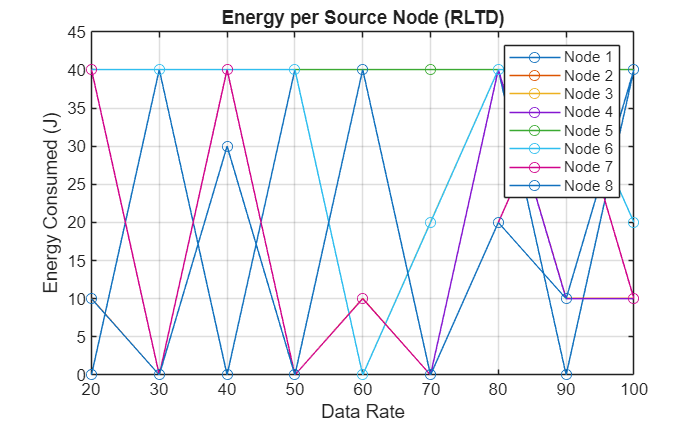


figure;
for s = 1:numSources
    plot(dataRates, energyPerSource(:,s), '-o', 'DisplayName', ['Node ' num2str(s)]); hold on;
end
xlabel('Data Rate'); ylabel('Energy Consumed (J)');
title('Energy per Source Node (RLTD)'); legend show; grid on;